# Projeto ATD2025


% Usando participante 6


## 1 & 2

caminhoBase = 'C:\Users\migas\Desktop\UC\2º ano\2º semestre\ATD\ATDProjeto\data\06';

arquivosAudio = dir(fullfile(caminhoBase, '*.wav'));

colunas = {'Diretorio', 'NomeFicheiro', 'Participante', 'Digito', 'Repeticao', 'TaxaAmostragem', 'Sinal'};
tabelaAudios = table('Size', [0, length(colunas)], 'VariableTypes', {'string', 'string', 'string', 'string', 'double', 'double', 'cell'}, 'VariableNames', colunas);

for i = 1:length(arquivosAudio)

    nomeFicheiro = arquivosAudio(i).name;

    caminhoCompleto = fullfile(caminhoBase, nomeFicheiro);
    
    partes = split(nomeFicheiro, '_');
    digito = partes{1};
    participante = partes{2};
    repeticao = str2double(erase(partes{3}, '.wav'));
    
    % Importar o sinal de áudio e a taxa de amostragem com audioread
    [sinal, taxaAmostragem] = audioread(caminhoCompleto);
    
    novaLinha = {caminhoCompleto, nomeFicheiro, participante, digito, repeticao, taxaAmostragem, {sinal}};
    tabelaAudios = [tabelaAudios; novaLinha];
end

disp(tabelaAudios)

                                        Diretorio                                        NomeFicheiro     Participante    Digito    Repeticao    TaxaAmostragem         Sinal      
    _________________________________________________________________________________    _____________    ____________    ______    _________    ______________    ________________

    "C:\Users\migas\Desktop\UC\2º ano\2º semestre\ATD\ATDProjeto\data\06\0_06_0.wav"     "0_06_0.wav"         "06"         "0"          0            48000         {31228×1 double}
    "C:\Users\migas\Desktop\UC\2º ano\2º semestre\ATD\ATDProjeto\data\06\0_06_1.wav"     "0_06_1.wav"         "06"         "0"          1            48000         {27853×1 double}
    "C:\Users\migas\Desktop\UC\2º ano\2º 

## 3

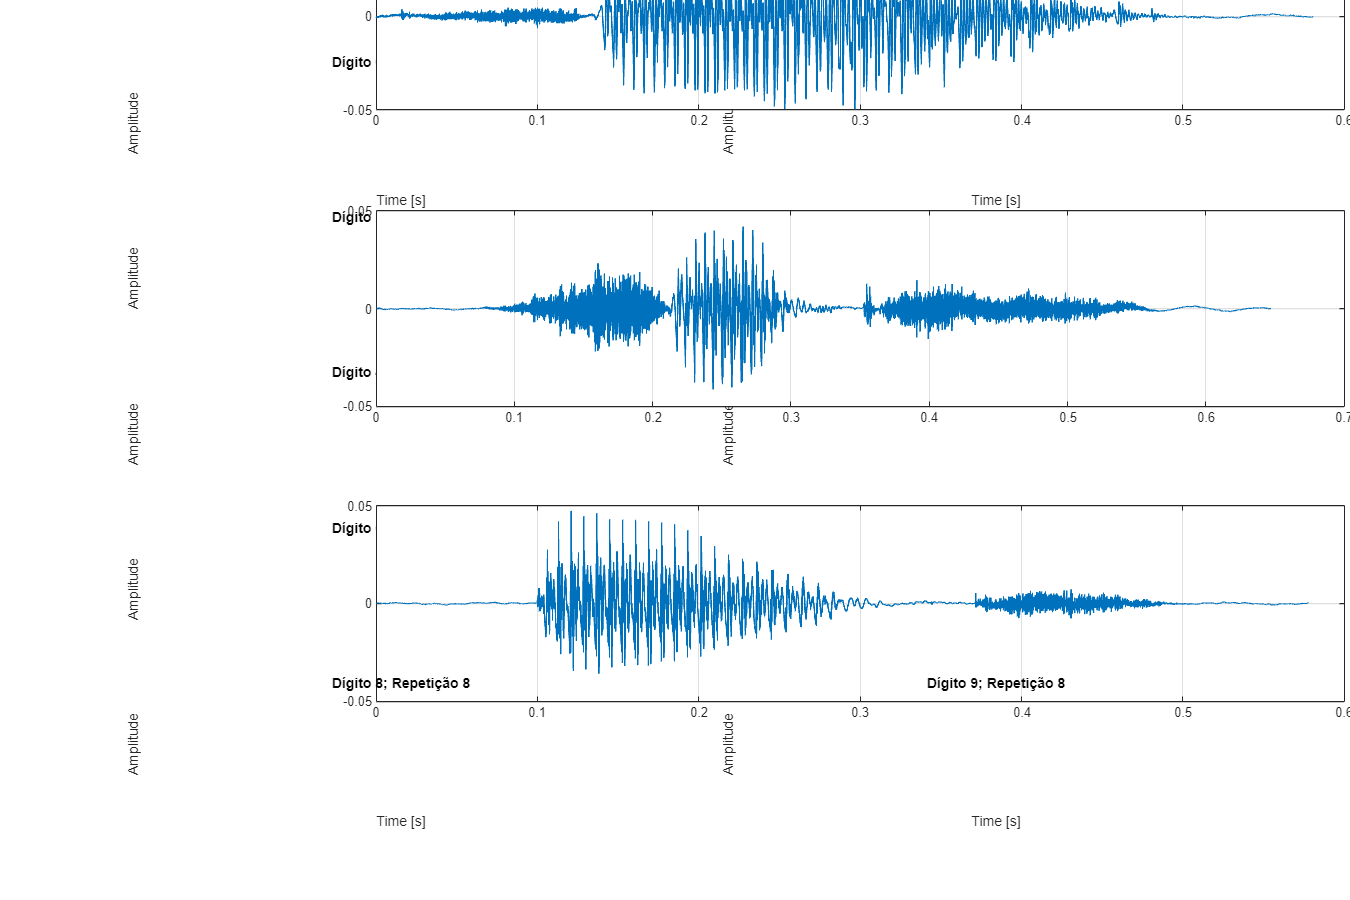


figure('Position', [100, 100, 1200, 800]);

for i = 1:length(arquivosAudio)
    nomeFicheiro = arquivosAudio(i).name;
    caminhoCompleto = fullfile(caminhoBase, nomeFicheiro);
    
    partes = split(nomeFicheiro, '_');
    digito = partes{1};
    repeticao = str2double(erase(partes{3}, '.wav'));

    if repeticao == 8
        [sinal, taxaAmostragem] = audioread(caminhoCompleto);
        
        % Calcular o vetor de tempo
        tempo = (0:length(sinal)-1) / taxaAmostragem;
        
        % Criar o gráfico no subplot
        subplot(5, 2, str2double(digito) + 1);
        plot(tempo, sinal);
        title(['Dígito ', digito, '; Repetição ', num2str(repeticao)]);
        xlabel('Time [s]');
        ylabel('Amplitude');
        grid on;
    end
end

## 4 & 5

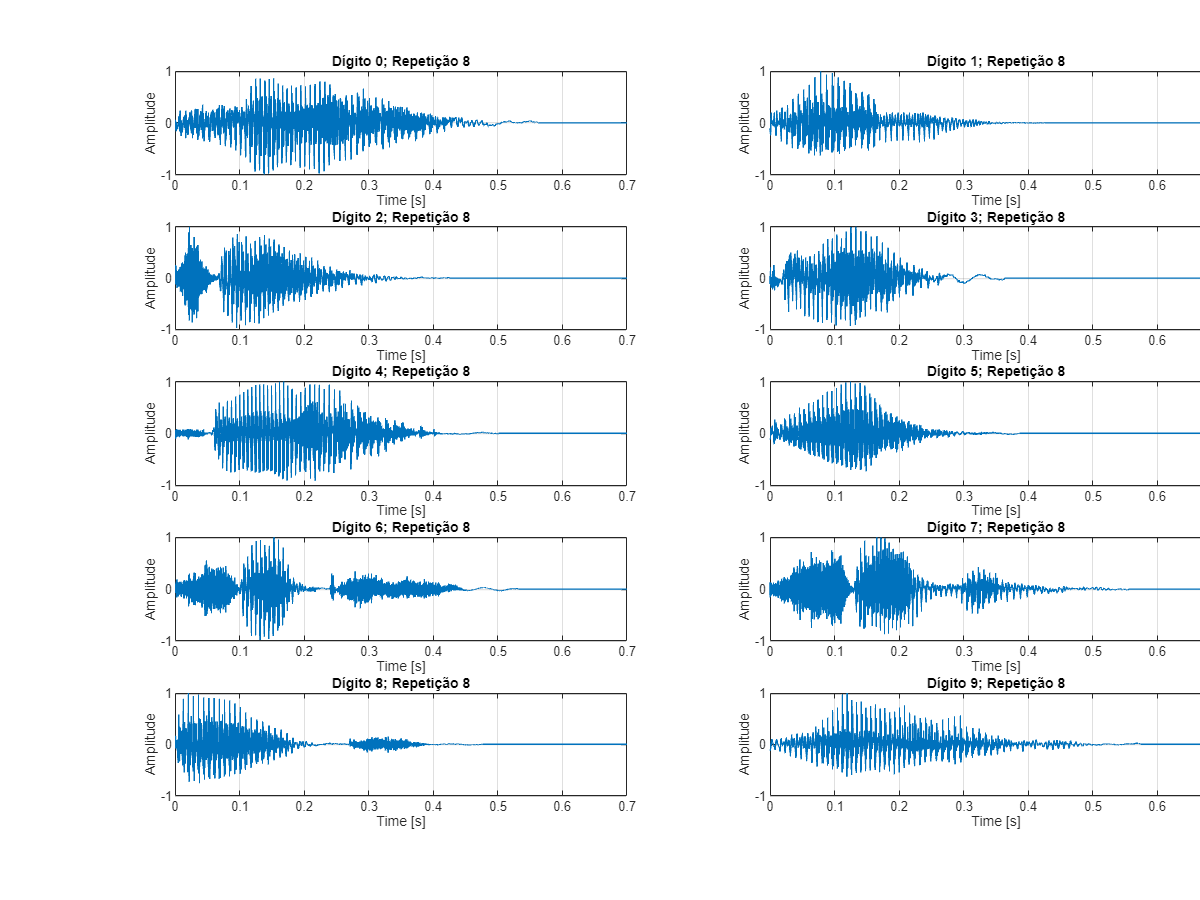

% Adicionar a coluna SinalPreProcessado à tabela
tabelaAudios.SinalPreProcessado = cell(height(tabelaAudios), 1);

figure('Position', [100, 100, 1200, 800]);

% Aplicar pré-processamento a lista toda e plotar os sinais da repetição 7
for i = 1:height(tabelaAudios)
    sinal = tabelaAudios.Sinal{i};
    taxaAmostragem = tabelaAudios.TaxaAmostragem(i);
    repeticao = tabelaAudios.Repeticao(i);
    digito = tabelaAudios.Digito(i);
    
    % Remover o silêncio inicial
    limiarEnergia = 0.01 * max(sinal.^2); % Limiar baseado na energia máxima, usando valor 0.01
    energia = sinal.^2;
    inicio = find(energia > limiarEnergia, 1, 'first');
    if isempty(inicio) % Caso nao encontre silencio usa tudo
        inicio = 1;
    end
    sinal = sinal(inicio:end);
    
    % Normalizar a amplitude
    sinal = sinal / max(abs(sinal)); % Normalizar para amplitude máxima = 1
    
    % Ajustar a duração
    amostrasDesejadas = round(0.7 * taxaAmostragem); % 0.7 é a duracao que queremos
    if length(sinal) < amostrasDesejadas
        % Adicionar silêncio no final
        sinal = [sinal; zeros(amostrasDesejadas - length(sinal), 1)];
    elseif length(sinal) > amostrasDesejadas
        % Corte de sinal, so para prevenir
        sinal = sinal(1:amostrasDesejadas);
    end
    
    % Guardar o sinal pré-processado na tabela
    tabelaAudios.SinalPreProcessado{i} = sinal;
    
    if repeticao == 8
        % Calcular o vetor de tempo
        tempo = (0:length(sinal)-1) / taxaAmostragem;
        
        % Criar o gráfico no subplot
        subplot(5, 2, str2double(digito) + 1);
        plot(tempo, sinal);
        title(sprintf('Dígito %s; Repetição %d', digito, repeticao));
        xlabel('Time [s]');
        ylabel('Amplitude');
        grid on;
    end
end

## 6

%{ 

Comparação gráficos antes/depois do pré-processamento

 Antes do pré-processamento:

       Silêncio inicial variável e amplitudes desalinhadas/desfasadas dificultavam a identificação 
       de padrões, isto é, as amostras iniciavam em pontos do tempo diferentes e as amplitudes eram 
       variantes provavelmente por fatores externos como: aproximação ao microfone ou ruído.

 Após pré-processamento (alinhamento + normalização):

      Com este processamento obtemos padrões temporais claros, energia
      temporal diferenciável e facilidade na determinação da duração do segmento ativo.
      São precisamente estas características que nos permitirão
      distinguir os diferentes dígitos.

%} 

## 7

numJanelas = 5;  % Número de janelas

% Características globais
tabelaAudios.EnergiaTotal = zeros(height(tabelaAudios), 1);
tabelaAudios.AmplitudeMaxima = zeros(height(tabelaAudios), 1);
tabelaAudios.AmplitudeMinima = zeros(height(tabelaAudios), 1);
tabelaAudios.DesvioPadrao = zeros(height(tabelaAudios), 1);
tabelaAudios.ValorMedioAmplitude = zeros(height(tabelaAudios), 1);

% Características por janela
for j = 1:numJanelas
    tabelaAudios.(['EnergiaJan_' num2str(j)]) = zeros(height(tabelaAudios), 1);
    tabelaAudios.(['AmpMaxJan_' num2str(j)]) = zeros(height(tabelaAudios), 1);
    tabelaAudios.(['AmpMinJan_' num2str(j)]) = zeros(height(tabelaAudios), 1);
    tabelaAudios.(['DesvPadJan_' num2str(j)]) = zeros(height(tabelaAudios), 1);
    tabelaAudios.(['AmpMediaJan_' num2str(j)]) = zeros(height(tabelaAudios), 1);
end

% Calcular características para cada sinal
for i = 1:height(tabelaAudios)
    sinal = tabelaAudios.SinalPreProcessado{i};
    N = length(sinal);
    tamanhoJanela = floor(N / numJanelas);
    
    % Características globais
    tabelaAudios.EnergiaTotal(i) = sum(sinal.^2);
    tabelaAudios.AmplitudeMaxima(i) = max(abs(sinal));
    tabelaAudios.AmplitudeMinima(i) = min(abs(sinal));
    tabelaAudios.DesvioPadrao(i) = std(sinal);
    tabelaAudios.ValorMedioAmplitude(i) = mean(abs(sinal));
    
    % Características por janela
    for j = 1:numJanelas
        inicio = (j-1)*tamanhoJanela + 1;
        fim = j*tamanhoJanela;
        if j == numJanelas  % A última janela pode ser maior
            fim = N;
        end
        janela = sinal(inicio:fim);
        
        % Características para esta janela
        tabelaAudios.(['EnergiaJan_' num2str(j)])(i) = sum(janela.^2);
        tabelaAudios.(['AmpMaxJan_' num2str(j)])(i) = max(abs(janela));
        tabelaAudios.(['AmpMinJan_' num2str(j)])(i) = min(abs(janela));
        tabelaAudios.(['DesvPadJan_' num2str(j)])(i) = std(janela);
        tabelaAudios.(['AmpMediaJan_' num2str(j)])(i) = mean(abs(janela));
    end
end

disp(tabelaAudios);

                                        Diretorio                                        NomeFicheiro     Participante    Digito    Repeticao    TaxaAmostragem         Sinal          SinalPreProcessado    EnergiaTotal    AmplitudeMaxima    AmplitudeMinima    DesvioPadrao    ValorMedioAmplitude    EnergiaJan_1    AmpMaxJan_1    AmpMinJan_1    DesvPadJan_1    AmpMediaJan_1    EnergiaJan_2    AmpMaxJan_2    AmpMinJan_2    DesvPadJan_2    AmpMediaJan_2    EnergiaJan_3    AmpMaxJan_3    AmpMinJan_3    DesvPadJan_3    AmpMediaJan_3</

## 8

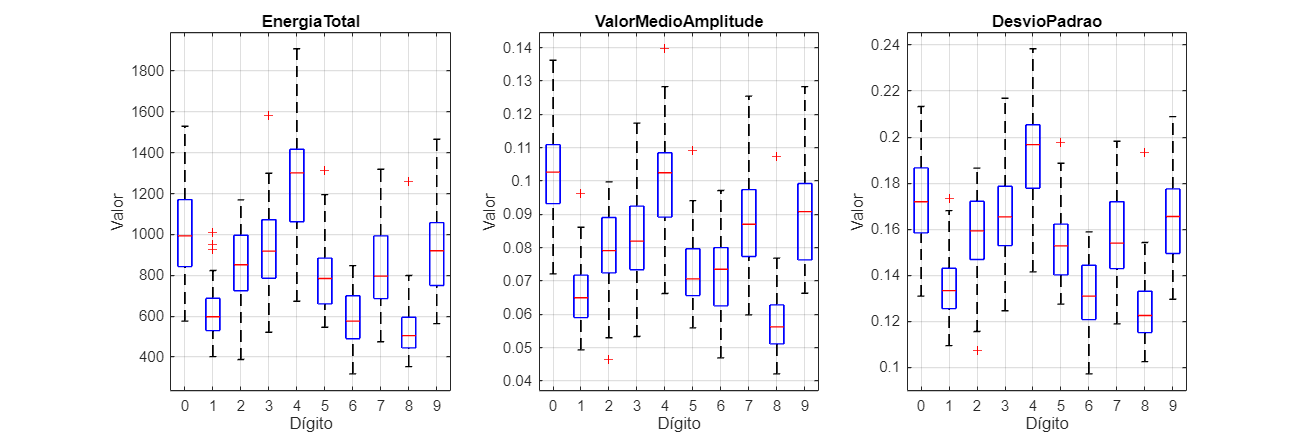

caracteristicasGlobais = {'EnergiaTotal', 'ValorMedioAmplitude', 'DesvioPadrao'};
caracteristicasJanela = {'EnergiaJan_', 'DesvPadJan_', 'AmpMediaJan_'}; %'EnergiaTotal', 'ValorMedioAmplitude', 'DesvioPadrao'

% Características globais
figure('Position', [100, 100, 1200, 400]);
for c = 1:length(caracteristicasGlobais)
    subplot(1, 3, c);
    boxplot(tabelaAudios.(caracteristicasGlobais{c}), tabelaAudios.Digito);
    title(caracteristicasGlobais{c});
    xlabel('Dígito');
    ylabel('Valor');
    grid on;
end

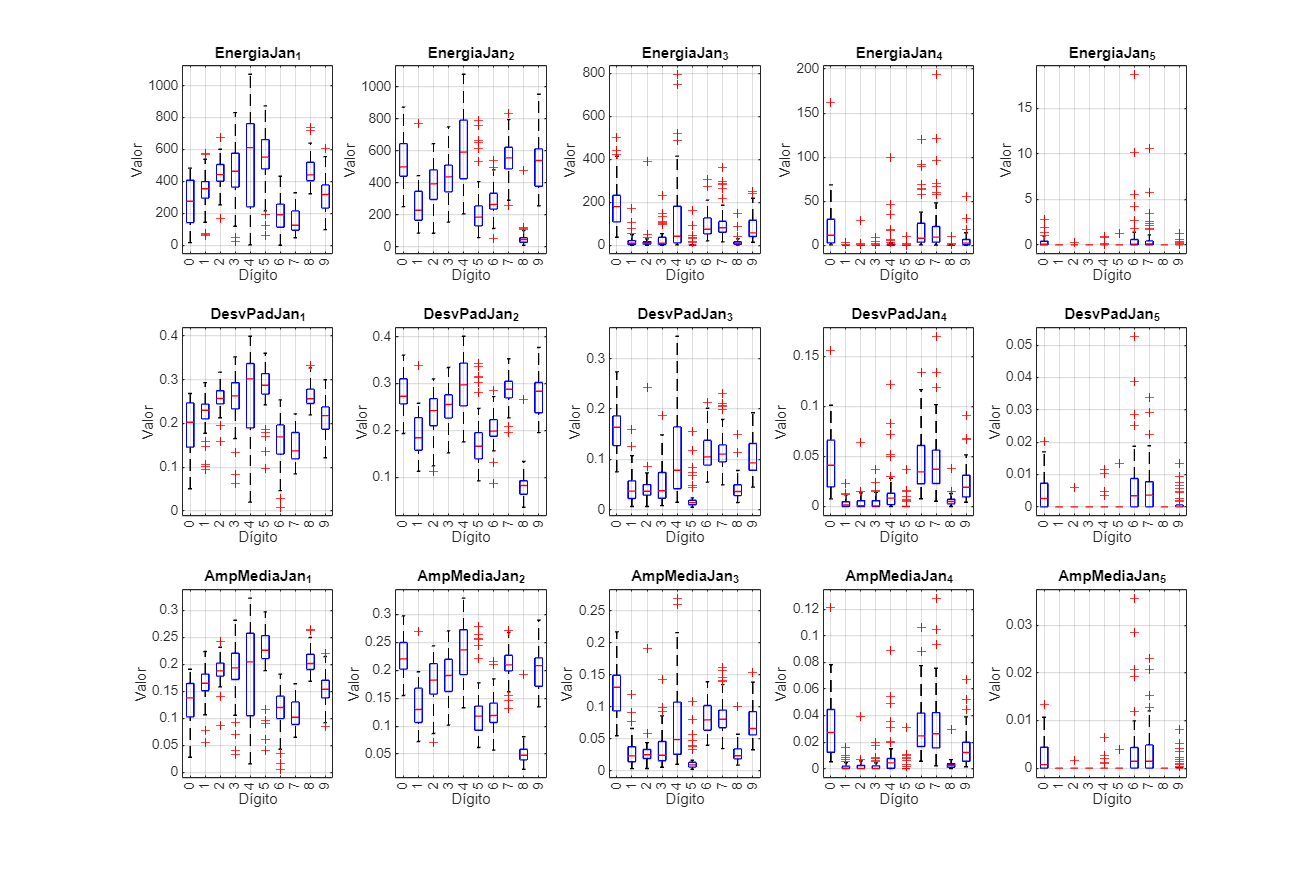


% Criar figura para características por janela
figure('Position', [100, 100, 1200, 800]);
for c = 1:length(caracteristicasJanela)
    for j = 1:numJanelas
        subplot(length(caracteristicasJanela), numJanelas, (c-1)*numJanelas + j);
        boxplot(tabelaAudios.([caracteristicasJanela{c} num2str(j)]), tabelaAudios.Digito);
        title([caracteristicasJanela{c} num2str(j)]);
        xlabel('Dígito');
        ylabel('Valor');
        grid on;
    end
end

## 9

tabelaAudios = removevars(tabelaAudios, 'Sinal');
save('dados_processados.mat', 'tabelaAudios');

## 10

load("dados_processados.mat");

## 11

tabelaAudios.CoeficientesFourier = cell(height(tabelaAudios), 1);

for i = 1:height(tabelaAudios)
    sinalPreProcessado = tabelaAudios.SinalPreProcessado{i};
    N = length(sinalPreProcessado);
    
    % Calcular os coeficientes de Fourier usando a FFT
    coeficientesFourier = fft(sinalPreProcessado) / N;
    
    tabelaAudios.CoeficientesFourier{i} = coeficientesFourier;
end

disp(tabelaAudios);

                                        Diretorio                                        NomeFicheiro     Participante    Digito    Repeticao    TaxaAmostragem    SinalPreProcessado    EnergiaTotal    AmplitudeMaxima    AmplitudeMinima    DesvioPadrao    ValorMedioAmplitude    EnergiaJan_1    AmpMaxJan_1    AmpMinJan_1    DesvPadJan_1    AmpMediaJan_1    EnergiaJan_2    AmpMaxJan_2    AmpMinJan_2    DesvPadJan_2    AmpMediaJan_2    EnergiaJan_3    AmpMaxJan_3    AmpMinJan_3    DesvPadJan_3    AmpMediaJan_3    EnergiaJan_4

## 12

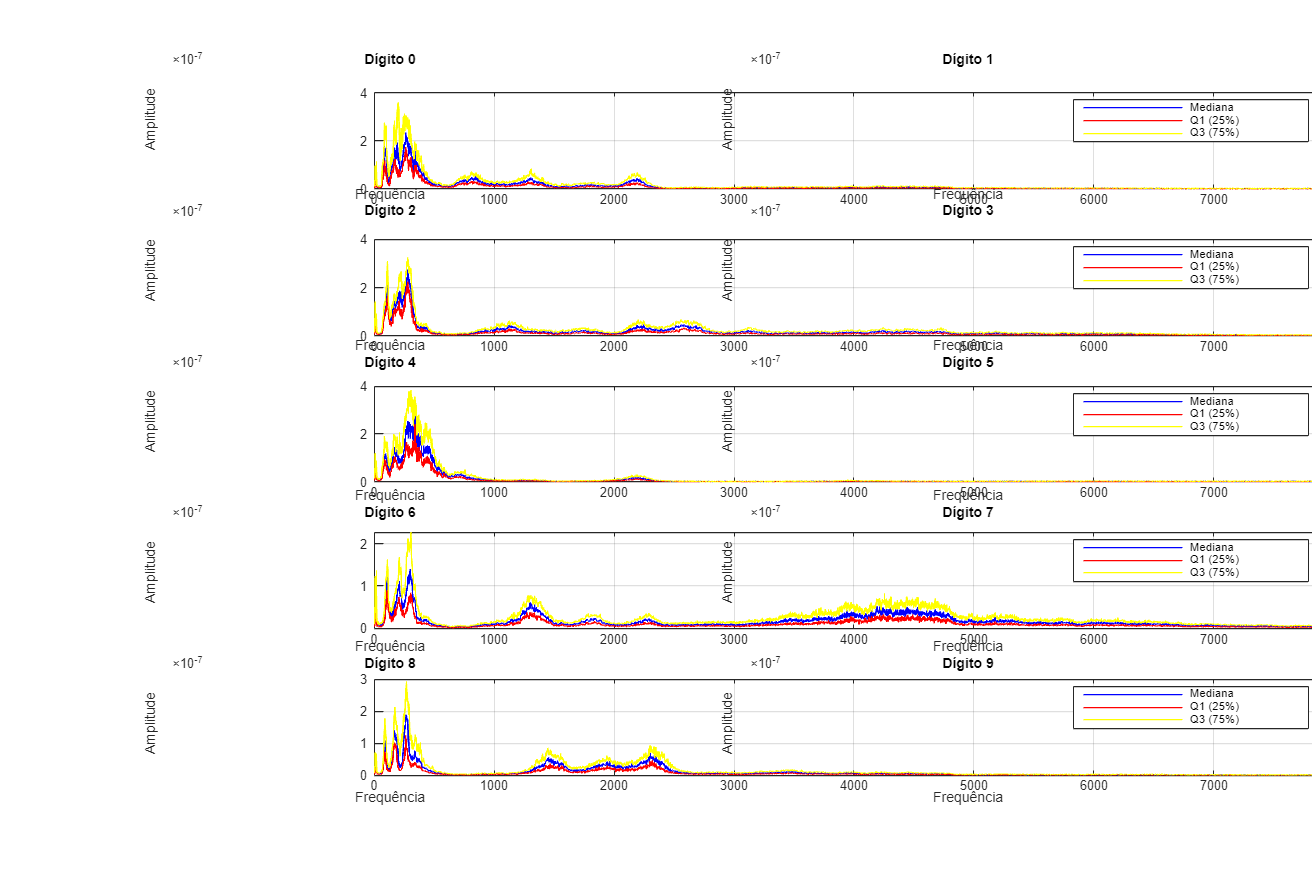

numDigitos = 10;

% Inicializar matrizes para armazenar os espectros de amplitude
espectroMediano = cell(numDigitos, 1);
espectroQ1 = cell(numDigitos, 1);
espectroQ3 = cell(numDigitos, 1);

% Frequências positivas (metade do espectro)
for digito = 0:9
    % Filtrar os sinais correspondentes ao dígito atual
    indicesDigito = str2double(tabelaAudios.Digito) == digito;
    coeficientesDigito = tabelaAudios.CoeficientesFourier(indicesDigito);
    
    % Inicializar matriz para armazenar os espectros de amplitude normalizados
    espectrosAmplitude = [];
    
    % Calcular o espectro de amplitude para cada sinal do dígito
    for i = 1:length(coeficientesDigito)
        coeficientes = coeficientesDigito{i};
        N = length(coeficientes);
        
        % Módulo dos coeficientes de Fourier (espectro de amplitude)
        espectroAmplitude = abs(coeficientes);
        
        % Normalizar pelo número de amostras
        espectroAmplitude = espectroAmplitude / N;
        
        % Manter apenas as frequências positivas (metade do espectro)
        espectroAmplitude = espectroAmplitude(1:floor(N/2)+1);
        
        % Armazenar o espectro de amplitude
        espectrosAmplitude = [espectrosAmplitude; espectroAmplitude'];
    end
    
    % Calcular a mediana, primeiro quartil e terceiro quartil
    espectroMediano{digito+1} = median(espectrosAmplitude, 1);
    espectroQ1{digito+1} = quantile(espectrosAmplitude, 0.25, 1);
    espectroQ3{digito+1} = quantile(espectrosAmplitude, 0.75, 1);
end

% Plotar os gráficos para cada dígito
figure('Position', [100, 100, 1200, 800]);

for digito = 0:9
    subplot(5, 2, digito+1); % 5 linhas e 2 colunas
    
    % Obter os espectros para o dígito atual
    mediano = espectroMediano{digito+1};
    q1 = espectroQ1{digito+1};
    q3 = espectroQ3{digito+1};
    
    % Limitar o eixo X até 8000 índices de frequência
    indicesFrequencia = 1:min(8000, length(mediano));
    
    % Plotar a mediana, primeiro quartil e terceiro quartil
    plot(indicesFrequencia, mediano(indicesFrequencia), 'b'); % Mediana em azul
    hold on;
    plot(indicesFrequencia, q1(indicesFrequencia), 'r'); % Q1 em laranja
    plot(indicesFrequencia, q3(indicesFrequencia), 'y'); % Q3 em amarelo
    
    % Configurações do gráfico
    title(['Dígito ', num2str(digito)]);
    xlabel('Frequência');
    ylabel('Amplitude');
    grid on;
    legend('Mediana', 'Q1 (25%)', 'Q3 (75%)');
end

## 13

numJanelasEspectrais = 5;

% Características globais
tabelaAudios.MaxFreq = zeros(height(tabelaAudios), 1);
tabelaAudios.MaxAmp = zeros(height(tabelaAudios), 1);
tabelaAudios.MediaEspectral = zeros(height(tabelaAudios), 1);
tabelaAudios.EdgeFreq85 = zeros(height(tabelaAudios), 1);
tabelaAudios.Entropia = zeros(height(tabelaAudios), 1);

% Características por janela
for j = 1:numJanelas
    tabelaAudios.(['MaxFreqJan_' num2str(j)]) = zeros(height(tabelaAudios), 1);
    tabelaAudios.(['MaxAmpJan_' num2str(j)]) = zeros(height(tabelaAudios), 1);
    tabelaAudios.(['MediaJan_' num2str(j)]) = zeros(height(tabelaAudios), 1);
    tabelaAudios.(['EdgeFreq85Jan_' num2str(j)]) = zeros(height(tabelaAudios), 1);
    tabelaAudios.(['EntropiaJan_' num2str(j)]) = zeros(height(tabelaAudios), 1);
end

% Calcular características para cada sinal
for i = 1:height(tabelaAudios)
    sinal = tabelaAudios.SinalPreProcessado{i};
    taxaAmostragem = tabelaAudios.TaxaAmostragem(i);
    N = length(sinal);
    
    % Características Globais
    fftGlobal = fft(sinal);
    N_fft = length(fftGlobal);
    espectroGlobal = abs(fftGlobal(1:floor(N_fft/2)+1))/N_fft;
    freqsGlobal = (0:floor(N_fft/2))*(taxaAmostragem/N_fft);
    
    % Máximo (Frequencia e Amplitude)
    [maxAmp, idx] = max(espectroGlobal);
    tabelaAudios.MaxFreq(i) = freqsGlobal(idx);
    tabelaAudios.MaxAmp(i) = maxAmp;
    
    % Média
    tabelaAudios.MediaEspectral(i) = mean(espectroGlobal);
    
    % Spectral Edge Frequency (85%)
    energiaTotal = sum(espectroGlobal.^2);
    energiaAcumulada = cumsum(espectroGlobal.^2);
    idx85 = find(energiaAcumulada >= 0.85*energiaTotal, 1);
    tabelaAudios.EdgeFreq85(i) = freqsGlobal(idx85);
    
    % Entropia
    espectroNorm = espectroGlobal/sum(espectroGlobal);
    tabelaAudios.Entropia(i) = -sum(espectroNorm.*log2(espectroNorm + eps));
    
    % Características Janela
    tamanhoJanela = floor(N / numJanelas);
    
    for j = 1:numJanelas
        inicio = (j-1)*tamanhoJanela + 1;
        fim = j*tamanhoJanela;
        if j == numJanelas
            fim = N;
        end
        janela = sinal(inicio:fim);
        
        % Transformada de Fourier da janela
        fftJanela = fft(janela);
        N_fft = length(fftJanela);
        espectro = abs(fftJanela(1:floor(N_fft/2)+1))/N_fft;
        freqs = (0:floor(N_fft/2))*(taxaAmostragem/N_fft);
        
        % Máximos espectral (Frequencia e Amplitude)
        [maxAmp, idx] = max(espectro);
        tabelaAudios.(['MaxFreqJan_' num2str(j)])(i) = freqs(idx);
        tabelaAudios.(['MaxAmpJan_' num2str(j)])(i) = maxAmp;
        
        % Média espectral
        tabelaAudios.(['MediaJan_' num2str(j)])(i) = mean(espectro);
        
        % Spectral Edge Frequency (85%)
        energiaTotal = sum(espectro.^2);
        energiaAcumulada = cumsum(espectro.^2);
        idx85 = find(energiaAcumulada >= 0.85*energiaTotal, 1);
        tabelaAudios.(['EdgeFreq85Jan_' num2str(j)])(i) = freqs(idx85);
        
        % Entropia espectral
        espectroNorm = espectro/sum(espectro);
        tabelaAudios.(['EntropiaJan_' num2str(j)])(i) = -sum(espectroNorm.*log2(espectroNorm + eps));
    end
end

disp(tabelaAudios);

                                        Diretorio                                        NomeFicheiro     Participante    Digito    Repeticao    TaxaAmostragem    SinalPreProcessado    EnergiaTotal    AmplitudeMaxima    AmplitudeMinima    DesvioPadrao    ValorMedioAmplitude    EnergiaJan_1    AmpMaxJan_1    AmpMinJan_1    DesvPadJan_1    AmpMediaJan_1    EnergiaJan_2    AmpMaxJan_2    AmpMinJan_2    DesvPadJan_2    AmpMediaJan_2    EnergiaJan_3    AmpMaxJan_3    AmpMinJan_3    DesvPadJan_3    AmpMediaJan_3    EnergiaJan_4

## 14


figure('Position', [100, 100, 1200, 400]);
caractGlobais = {'MediaEspectral', 'EdgeFreq85', 'Entropia'};

% Características globais
for c = 1:length(caractGlobais)
    subplot(1, 3, c);
    boxplot(tabelaAudios.(caractGlobais{c}), tabelaAudios.Digito);
    title(caractGlobais{c});
    xlabel('Dígito');
    ylabel('Valor');
    grid on;
end

figure('Position', [100, 100, 1200, 800]);

caracteristicasPlot = {
    'EdgeFreq85Jan_',
    'EntropiaJan_'
};

for c = 1:length(caracteristicasPlot)
    for j = 1:numJanelas
        subplot(2, 5, (c-1)*5 + j);
        
        boxplot(tabelaAudios.([caracteristicasPlot{c} num2str(j)]), tabelaAudios.Digito);
        
        title([strrep(caracteristicasPlot{c}, '_', ' ') num2str(j)]);
        xlabel('Dígito');
        ylabel('Valor');
        grid on;
    
        maxY = max(tabelaAudios.([caracteristicasPlot{c} num2str(j)]));
        minY = min(tabelaAudios.([caracteristicasPlot{c} num2str(j)]));
        ylim([minY*1.1, maxY*1.1]);
    end
end

## 15

save('dados_processados.mat', 'tabelaAudios');

## 16

load('dados_processados.mat');

## 17

caracteristicasTemporais = {'EnergiaJan_2', 'DesvPadJan_1', 'AmpMediaJan_2'};
caracteristicasEspectrais = {'MediaJan_2', 'EdgeFreq85Jan_1', 'EntropiaJan_1'};

% Criar matriz de características (X) e vetor de labels (y)
X = [];
y = str2double(tabelaAudios.Digito);

% Adicionar características temporais
for i = 1:length(caracteristicasTemporais)
    X = [X, tabelaAudios.(caracteristicasTemporais{i})];
end

% Adicionar características espectrais
for i = 1:length(caracteristicasEspectrais)
    X = [X, tabelaAudios.(caracteristicasEspectrais{i})];
end

% Normalizar as características
X = normalize(X);

% Dividir os dados em treino (70%) e teste (30%)
rng(1); % Para reprodutibilidade
cv = cvpartition(y, 'HoldOut', 0.3);
idxTreino = training(cv);
idxTeste = test(cv);

X_treino = X(idxTreino, :);
y_treino = y(idxTreino);
X_teste = X(idxTeste, :);
y_teste = y(idxTeste);

% Árvore de Decisão
tree = fitctree(X_treino, y_treino);
y_pred = predict(tree, X_teste);

% Guardar resultados na tabela
tabelaAudios.Classificacao = zeros(height(tabelaAudios), 1);
tabelaAudios.Classificacao(idxTeste) = y_pred;

## 18

exatidao = sum(y_pred == y_teste) / length(y_teste) * 100;
disp(['Exatidão: ', num2str(exatidao), '%']);

Exatidão: 78%


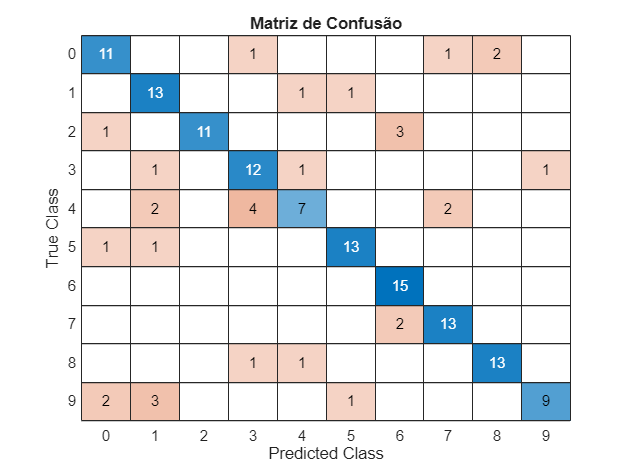

% Matriz de confusão para comparar
figure;
confusionchart(y_teste, y_pred);
title('Matriz de Confusão');

## 19

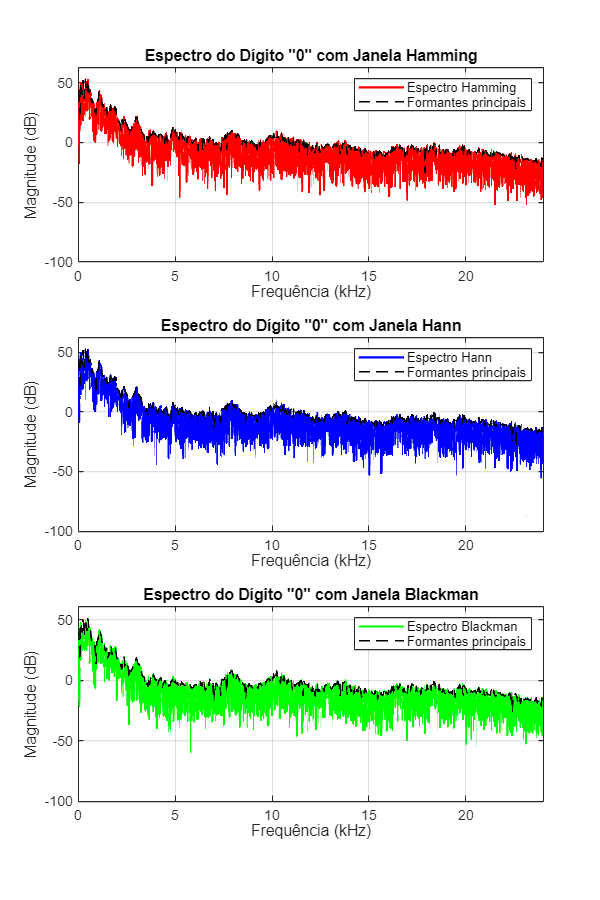

% Parâmetros
N = length(tabelaAudios.SinalPreProcessado{1}); % Tamanho do sinal
fs = tabelaAudios.TaxaAmostragem(1); % Taxa de amostragem
janelas = {'hamming', 'hann', 'blackman'};
nomes = {'Hamming', 'Hann', 'Blackman'};
cores = {'r', 'b', 'g'};

% Selecionar um sinal de exemplo (digito 0, primeira repetição)
idx_exemplo = find(str2double(tabelaAudios.Digito)==0 & tabelaAudios.Repeticao==1, 1);
sinal_exemplo = tabelaAudios.SinalPreProcessado{idx_exemplo};

% Configurar figura
figure('Position', [100, 100, 600, 900]);

% Processar e plotar cada janela separadamente
for i = 1:length(janelas)
    % Criar e aplicar a janela
    w = window(janelas{i}, N);
    sinal_windowed = sinal_exemplo .* w;
    
    % Calcular FFT
    N_fft = 2^nextpow2(N);
    W = fft(sinal_windowed, N_fft);
    W_mag = 20*log10(abs(W(1:N_fft/2+1))); % em dB
    freq = (0:N_fft/2)*fs/N_fft; % Frequência em Hz
    
    % Plotar
    subplot(3,1,i);
    plot(freq/1000, W_mag, 'Color', cores{i}, 'LineWidth', 1.5);
    title(['Espectro do Dígito "0" com Janela ' nomes{i}]);
    xlabel('Frequência (kHz)');
    ylabel('Magnitude (dB)');
    xlim([0 fs/2000]); % Até metade da frequência de Nyquist
    ylim([-100 max(W_mag)+10]);
    grid on;
    
    % Destacar características importantes
    hold on;
    [pks,locs] = findpeaks(W_mag, 'MinPeakHeight',-50, 'MinPeakDistance',50);
    plot(locs*fs/N_fft/1000, pks, 'black--', 'MarkerSize', 10, 'LineWidth', 1);
    legend(['Espectro ' nomes{i}], 'Formantes principais');
end

## 20

save('dados_processados.mat', 'tabelaAudios');